# Desarrollo Laboratorio 3 - Robótica 2021-II

### Edgar Alejandro Ruíz Velasco

### Jesus Daniel Caballero Colina

### Jhohan David Contreras Aragón

**Para este equipo de trabajo se asignó el robot industrial *****Epson C4***

### Parte 1 Ruta:

El presente equipo de trabajo es el no. 6, por ende el plano vector asignado es $\left\lbrack 0,1,1\right\rbrack$. Además se seleccionó la ruta:

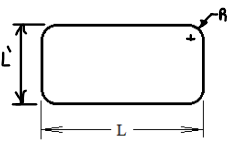

Donde L corresponde a 0.4 del alcance horizontal máximo del robot. Según el manual del robot C4 (investigación realizada en taller 1) el alcance horizontal máximo es de 665 mm, es decir que $L=0\ldotp 4\;\left(665\mathrm{mm}\right)=266\mathrm{mm}=26\ldotp 6\mathrm{cm}$. La otra dimensión del rectangulo se va a tomar como $L^{\prime } =0\ldotp 5L=133\mathrm{mm}=13\ldotp 3\mathrm{cm}$ y el radio de cada esquina se va a tomar como $R=20\mathrm{mm}=2\ldotp 0\mathrm{cm}$. Por último, el centro del rectangulo de la pista se posicionó $\left\lbrack x,y,z\right\rbrack =\left\lbrack 0,415,570\right\rbrack \mathrm{mm}=\left\lbrack 0,41\ldotp 5,57\ldotp 0\right\rbrack \mathrm{cm}$ (al nivel de la posición de calibración del robot pero rotado 90°).

Ahora se hallan los puntos de la ruta, siguiendo las dimensiones delimitadas anteriormente, en el plano XY y centrado en la posición de calibración del robot:

% Dimensiones y posición de ruta [cm]
P_centro = [0,41.5,57.0];
L = 26.6;
L1 = 13.3;
R = 2.0;
% Especificación de ruta
n = 200; %Número de viapoints

%--------------------------------------------
Perimetro = (L-2*R)*2 + (L1-2*R)*2 + 2*pi*R;
d = Perimetro / n; % Distancia entre puntos

viapoints = zeros(n,3);
% El primero punto se escoge en la posición superior central del rectangulo
i = 1;
x = 0;
while (x < L/2-R)
    viapoints(i,1:3) = [x,L1/2,0];
    x = x + d;
    i = i + 1;
end
d1 = x - (L/2-R);
theta1 = d1/R;
theta2 = d/R;

theta = theta1;
while theta < pi/2
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[L/2-R,L1/2-R,0];
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-pi/2))*R;
d2 = d - d1;

y = L1/2 - R - d2;
while y > R - L1/2
    viapoints(i,1:3) = [L/2,y,0];
    y = y - d;
    i = i + 1;
end
d1 = (R - L1/2) - y;
theta1 = d1/R;
theta2 = d/R;

theta = pi/2 + theta1;
while theta < pi
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[L/2-R,-L1/2+R,0];
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-pi))*R;
d2 = d - d1;

x = L/2 - R - d2;
while x > R - L/2
    viapoints(i,1:3) = [x,-L1/2,0];
    x = x - d;
    i = i + 1;
end
d1 = (R - L/2) - x;
theta1 = d1/R;
theta2 = d/R;

theta = pi + theta1;
while theta < 3*pi/2
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[-L/2+R,-L1/2+R,0];
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-3*pi/2))*R;
d2 = d - d1;

y = - L1/2 + R + d2;
while y < L1/2 - R
    viapoints(i,1:3) = [-L/2,y,0];
    y = y + d;
    i = i + 1;
end
d1 = y - (L1/2 - R);
theta1 = d1/R;
theta2 = d/R;

theta = 3*pi/2 + theta1;
while theta < 2*pi
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[-L/2+R,L1/2-R,0];
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-2*pi))*R;
d2 = d - d1;

x = -L/2 + R + d2;
while x < 0
    viapoints(i,1:3) = [x,L1/2,0];
    x = x + d;
    i = i + 1;
end

close all
figure("Name","Ruta")
hold on
for j = 1:n
   plot3(viapoints(j,1),viapoints(j,2),viapoints(j,3),'b.','MarkerSize',10);
end
xlim([-133 133])
ylim([348 482])

Teniendo los puntos en el plano XY se procede a rotar cada uno de tal manera que queden en el plano vector $\left\lbrack 0,1,1\right\rbrack$.

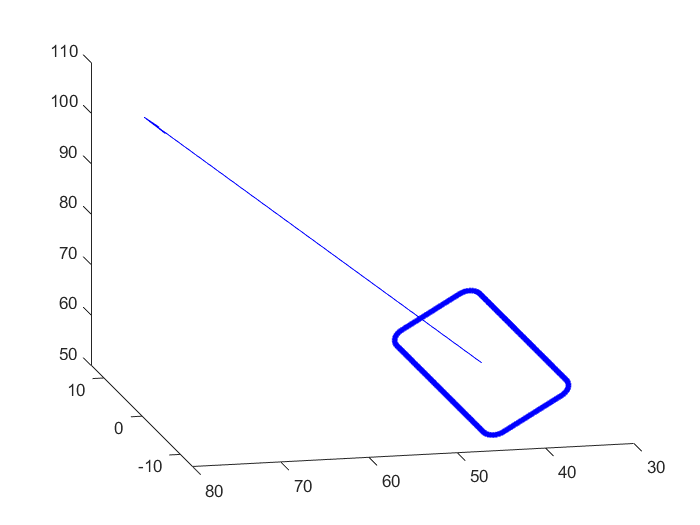

MTH = rotx(-pi/4);
for i = 1:n
    viapoints(i,1:3) = (MTH*viapoints(i,1:3)')'+P_centro;
end

close all
figure("Name","Ruta")
hold on
for j = 1:n
   plot3(viapoints(j,1),viapoints(j,2),viapoints(j,3),'b.','MarkerSize',10);
end
quiver3(P_centro(1),P_centro(2),P_centro(3),P_centro(1),P_centro(2)+1,P_centro(3)+1,'blue')
view([-103 19])

### Parte 2 Modelo diferencial de primer Orden:

Considerando que para que el robot ejecute los movimientos, se desea establecer una relacion entre las velocidades del efector final y las articulaciones.

1. Con los valores numericos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numericos, NO simbolico) en funcion de los angulos de articulacion. 

 2. Para una postura de su eleccion dentro del espacio diestro del robot obtenga las velocidades de articulacion para: 

%     MDHm(thetai,      di,    ai-1,  alpha-1,   sigma, offset)
Links(1) = Link('revolute','alpha',0,    'a',0, 'd',32, 'offset',0,'modified', 'qlim',[-17*pi/18 17*pi/18]);
Links(2) = Link('revolute','alpha',pi/2, 'a',10,'d',0,  'offset',pi/2,'modified', 'qlim',[-8*pi/9 13*pi/36]);
Links(3) = Link('revolute','alpha',0,    'a',25,'d',0,  'offset',0,   'modified', 'qlim',[-17*pi/60 5*pi/4]);
Links(4) = Link('revolute','alpha',-pi/2,'a',0, 'd',-25,'offset',0,   'modified', 'qlim',[-10*pi/9 10*pi/9]);
Links(5) = Link('revolute','alpha',pi/2, 'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-3*pi/4 3*pi/4]);
Links(6) = Link('revolute','alpha',-pi/2,'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-2*pi 2*pi]);
T_6_tool=[1 0 0 0; 0 -1 0 0; 0 0 -1 -6.5; 0 0 0 1];

Epson_C4 = SerialLink(Links,'name','Epson C4','tool',T_6_tool)

 
Epson_C4 = 
 
Epson C4 (6 axis, RRRRRR, modDH, fastRNE)                                     
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|         32|          0|          0|          0|             
|  2|         q2|          0|         10|      1.571|      1.571|             
|  3|         q3|          0|         25|          0|          0|             
|  4|         q4|        -25|          0|     -1.571|          0|             
|  5|         q5|          0|          0|      1.571|          0|             
|  6|         q6|          0|          0|     -1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                    


syms q1 q2 q3 q4 q5 q6 real
%Matrices MTH
T_0_1 = Epson_C4.A(1, [q1 q2 q3 q4 q5 q6]);
T_1_2 = Epson_C4.A(2, [q1 q2 q3 q4 q5 q6]);
T_2_3 = Epson_C4.A(3, [q1 q2 q3 q4 q5 q6]);
T_3_4 = Epson_C4.A(4, [q1 q2 q3 q4 q5 q6]);
T_4_5 = Epson_C4.A(5, [q1 q2 q3 q4 q5 q6]);
T_5_6 = Epson_C4.A(6, [q1 q2 q3 q4 q5 q6]);
%Matrices A
A_0_1 = simplify(T_0_1);
A_0_2 = simplify(A_0_1*T_1_2);
A_0_3 = simplify(A_0_2*T_2_3);
A_0_4 = simplify(A_0_3*T_3_4);
A_0_5 = simplify(A_0_4*T_4_5);
A_0_6 = simplify(A_0_5*T_5_6);
A_0_tool = A_0_6*T_6_tool;
%Vectores Z
z_0_1 = A_0_1(1:3,3);
z_0_2 = A_0_2(1:3,3);
z_0_3 = A_0_3(1:3,3);
z_0_4 = A_0_4(1:3,3);
z_0_5 = A_0_5(1:3,3);
z_0_6 = A_0_6(1:3,3);
%Vectores p=(r_n-r_i)
p_6_tool=A_0_tool(1:3,4)-A_0_6(1:3,4);
p_5_tool=A_0_tool(1:3,4)-A_0_5(1:3,4);
p_4_tool=A_0_tool(1:3,4)-A_0_4(1:3,4);
p_3_tool=A_0_tool(1:3,4)-A_0_3(1:3,4);
p_2_tool=A_0_tool(1:3,4)-A_0_2(1:3,4);
p_1_tool=A_0_tool(1:3,4)-A_0_1(1:3,4);

%Jacobianos
J1=[(skew(z_0_1)*p_1_tool); z_0_1]; %Rotacional
J2=[(skew(z_0_2)*p_2_tool); z_0_2]; %Rotacional
J3=[(skew(z_0_3)*p_3_tool); z_0_3]; %Rotacional
J4=[(skew(z_0_4)*p_4_tool); z_0_4]; %Rotacional
J5=[(skew(z_0_5)*p_5_tool); z_0_5]; %Rotacional
J6=[(skew(z_0_6)*p_6_tool); z_0_6]; %Rotacional
J_sym=([J1,J2,J3,J4,J5,J6]); %% Matriz jacobiana simbólica en función de q1,q2,q3,q4,q5 

Ahora se procede a escoger una postura arbitraria para probar el Jacobiano construido:

target=Epson_C4.fkine([pi/6 pi/6 pi/6 pi/6 pi/6 pi/6]);
qS=Epson_C4.ikunc(target);
q1=qS(1);
q2=qS(2);
q3=qS(3);
q4=qS(4);
q5=qS(5);
q6=qS(6);
Je=eval(J_sym) % Matriz jacobiana de valores numéricos para q=[pi/6 pi/6 pi/6 pi/6 pi/6 pi/6]

Je =    -6.5958  -42.9406  -24.1906   -0.1885   -6.4708   -0.0000
    8.1743  -24.7918  -13.9665    3.1411   -0.4859   -0.0000
         0    0.3771   12.8771   -0.8125   -0.3771    0.0000
         0    0.5000    0.5000   -0.4330    0.0580    0.0748
         0   -0.8660   -0.8660   -0.2500   -0.9665   -0.2455
    1.0000    0.0000    0.0000   -0.8660    0.2500   -0.9665


Por último se procede a hallar $\dot{x} =J\dot{q} \Rightarrow \dot{q} ={\left(J^T J\right)}^{-1} J^T \dot{x\;}$ (Tener en cuenta que el modelo del robot lo construimos en cm, y las velocidades lineales se dan en mm/s): 

q_p=inv((Je')*Je)*(Je')*([10 20 5 5 10 -5]');
q1_p=q_p(1)

q1_p = 7.2821

q2_p=q_p(2)

q2_p = 0.9640

q3_p=q_p(3)

q3_p = -0.6271

q4_p=q_p(4)

q4_p = -9.7336

q5_p=q_p(5)

q5_p = -12.7373

q6_p=q_p(6)

q6_p = 18.1347

### Parte 3 Integración:

Ahora con la ayuda de los algoritmos desarrollados y de la GUI construida. 

1. Ubique la ruta seleccionada con la orientación indicada dentro del espacio diestro del robot. 

REALIZADO TOTALMENTE EN LA PARTE 1

2. Defina un conjunto de puntos equidistantes que pertenezcan a la ruta (viapoints). Mínimo 60 puntos. El eje z de la herramienta debe mantenerse perpendicular al plano que contiene la ruta. 

T = zeros(4,4,n);
for i = 1:n
    T(:,:,i) = transl(viapoints(i,1:3))*trotx(-pi/4);
end

3. Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articulación al recorrer la ruta. 

q = zeros(n,6);
for i = 1:n
    q(i,:) = Epson_C4.ikunc(T(:,:,i));
end

Como se puede ver en las gráficas (mostradas más adelante, de color azul), los valores de q tienen valores atipicos, ocasionando que pueda haber movimientos inesperados del robot, por ello se procede a hacer 2 filtrados de estos valores mediante el métodos del relleno (el primero de color rojo y el segundo de color amarillo):

q1 = zeros(n,6);
q2 = zeros(n,6);
for i = 1:6
    q1(:,i) = filloutliers(q(:,i),'next');
    q2(:,i) = filloutliers(q1(:,i),'next');
end

Por último el vector de tiempo se calcula teniendo en cuenta la velocidad requerida (dada en el siguiente punto $v=500\mathrm{mm}/s=50cm/s$) y la distancia de desplazamiento entre viapoints (variable d), dando que $\Delta t=\frac{d}{v}$:

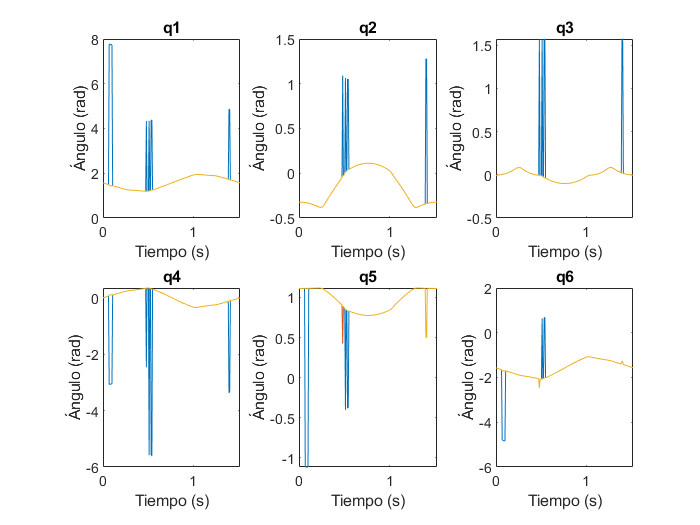

t = zeros(1,n);
v = 50;
dt = d/v;
for i=2:n
    t(1,i) = t(1,i-1) + dt;
end

figure('Name','Angulos')
subplot(2,3,1)
plot(t,q(:,1))
hold on
plot(t,q1(:,1))
plot(t,q2(:,1))
xlabel('Tiempo (s)')
ylabel('Ángulo (rad)')
title('q1')
subplot(2,3,2)
plot(t,q(:,2))
hold on
plot(t,q1(:,2))
plot(t,q2(:,2))
xlabel('Tiempo (s)')
ylabel('Ángulo (rad)')
title('q2')
subplot(2,3,3)
plot(t,q(:,3))
hold on
plot(t,q1(:,3))
plot(t,q2(:,3))
xlabel('Tiempo (s)')
ylabel('Ángulo (rad)')
title('q3')
subplot(2,3,4)
plot(t,q(:,4))
hold on
plot(t,q1(:,4))
plot(t,q2(:,4))
xlabel('Tiempo (s)')
ylabel('Ángulo (rad)')
title('q4')
subplot(2,3,5)
plot(t,q(:,5))
hold on
plot(t,q1(:,5))
plot(t,q2(:,5))
xlabel('Tiempo (s)')
ylabel('Ángulo (rad)')
title('q5')
subplot(2,3,6)
plot(t,q(:,6))
hold on
plot(t,q1(:,6))
plot(t,q2(:,6))
xlabel('Tiempo (s)')
ylabel('Ángulo (rad)')
title('q6')

4. Calcule las velocidades en cada viapoint de manera que la herramienta recorra la ruta a una velocidad de 500 mm/s. Presente gráficas de velocidad de cada articulación.

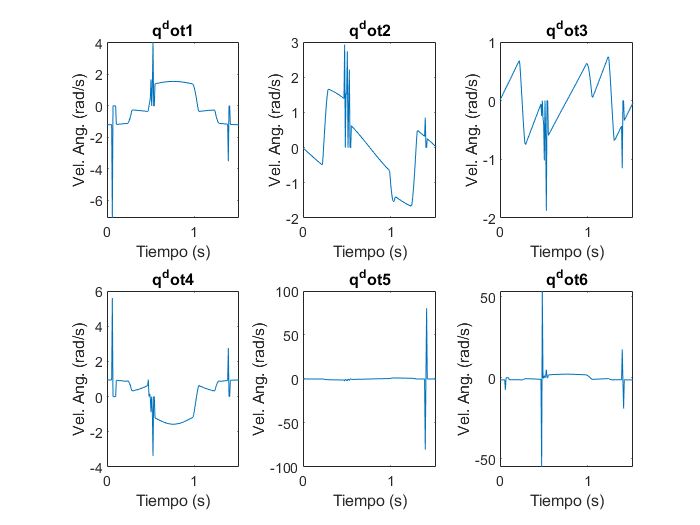

q_p = zeros(n-1,6);
for i=1:6
    for j=1:n-1
        q_p(j,i) = (q2(j+1,i)-q2(j,i))/dt;
    end
end
t=t(1:n-1);
figure('Name','Angulos')
subplot(2,3,1)
plot(t,q_p(:,1))
xlabel('Tiempo (s)')
ylabel('Vel. Ang. (rad/s)')
title('q^dot1')
subplot(2,3,2)
plot(t,q_p(:,2))
xlabel('Tiempo (s)')
ylabel('Vel. Ang. (rad/s)')
title('q^dot2')
subplot(2,3,3)
plot(t,q_p(:,3))
xlabel('Tiempo (s)')
ylabel('Vel. Ang. (rad/s)')
title('q^dot3')
subplot(2,3,4)
plot(t,q_p(:,4))
xlabel('Tiempo (s)')
ylabel('Vel. Ang. (rad/s)')
title('q^dot4')
subplot(2,3,5)
plot(t,q_p(:,5))
xlabel('Tiempo (s)')
ylabel('Vel. Ang. (rad/s)')
title('q^dot5')
subplot(2,3,6)
plot(t,q_p(:,6))
xlabel('Tiempo (s)')
ylabel('Vel. Ang. (rad/s)')
title('q^dot6')

Para comprobar los resultados obtenidos se creó la aplicación GUI para visualizar el recorrido realizado por el robot: